## **report 05/31**

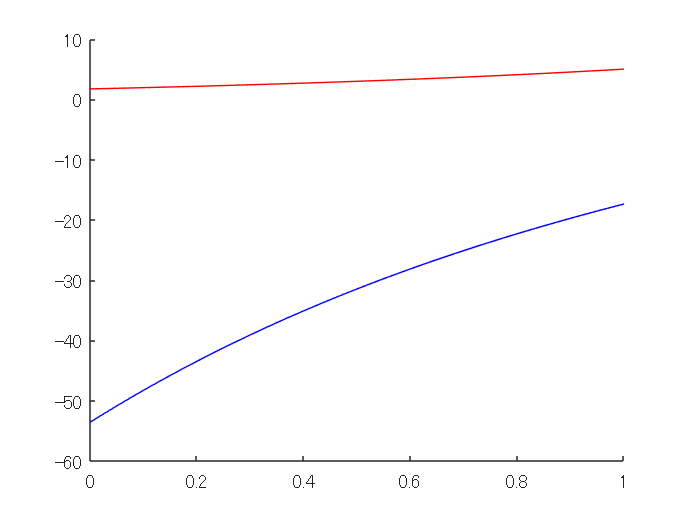

%k=1,a=1としてプロットして確認
A = (2*exp(-2)-4)/(-2);
B =  2*exp(-2)/(-2);
C = 1;
D = -exp(4);

x = linspace(0,1,100);
Bx = A*exp(x)+B*exp(-x);
Bxa = C*exp(x)+D*exp(-x);
figure;
hold on
plot(x,Bx,'r')
plot(x,Bxa,'b')
hold off

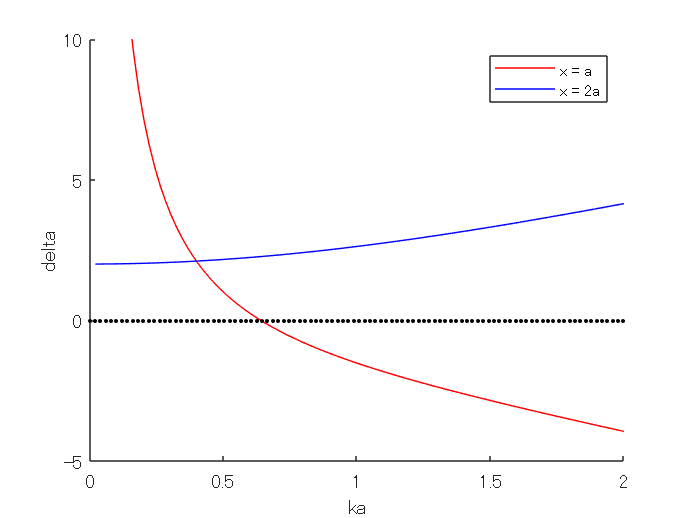

clear all;
ka = linspace(0,2,100);
zero_line = zeros(100);
delta1 = 2.*ka.*(exp(-2.*ka)-2.*ka+1)./(exp(-2.*ka)+2.*ka-1);
delta2 = 2.*ka.*(1+exp(-2.*ka))./(1-exp(-2.*ka));

figure;
hold on
plot(ka, delta1, 'r')
plot(ka, delta2, 'b')
plot(ka,zero_line,'k.')
hold off
xlabel('ka')
ylabel('delta')
legend('x = a','x = 2a')
xlim([0,2])
ylim([-5,10])